# Group Project: Virtual MRI Scanner

# Phantom Creation

function matrix = generatePhantoms(size, ellipses, addRectangle)
    matrix = phantom(ellipses, size);

    % Adds a rectangle to the matrix by defining a rectangular region in
    % which the signal intensity for pixels in this region is set appropriately
    if addRectangle == true
        [x, y] = deal(size);
        midX = x / 2;
        deltaX = x / 15;
        leftXBoundary = midX - deltaX;
        rightXBoundary= midX + deltaX;
    
        midY = y / 2;
        deltaY = y / 3.5;
        topYBoundary = midY - deltaY;
        bottomYBoundary= midY + deltaY;

        for i=1:x
            for j=1:y
                % Ensure current coordinate is within the rectangle's boundaries
                if (j >= leftXBoundary) && (j <= rightXBoundary) && (i >= topYBoundary) && (i <= bottomYBoundary)
                    matrix(i, j) = 1;
                end
            end
        end
    end
    figure, imshow(matrix)
end

phantomOne = [0.5 0.75 0.75 0 0 0];   % Outer circle ellipse (rectangle region added below)


phantomTwo = [0.5 0.75  0.75   0    0 0 % Outer circle ellipse
              1.0 0.20  0.20   0.5  0 0 % Right most inner circle ellipse
              1.0 0.15  0.15   0.1  0 0 % Second from right circle ellipse
              1.0 0.10  0.10  -0.2  0 0 % Third from right circle ellipse
              1.0 0.05  0.05  -0.4  0 0 % Fourth from right circle ellipse
              1.0 0.025 0.025 -0.52 0 0 % Left most inner circle ellipse
             ];

% Set size
N = 256; % GUI MODIFIED VARIABLE

% Generate phantoms
disp("Phantom One")

Phantom One


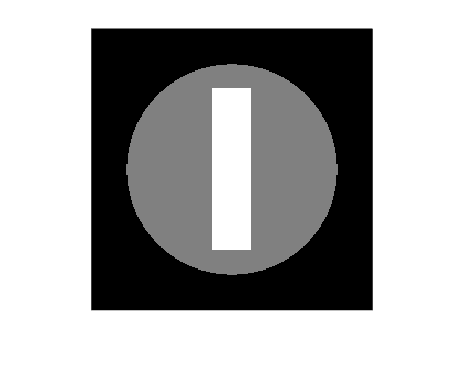

matrixOne = generatePhantoms(N, phantomOne, true);


disp("Phantom Two")

Phantom Two


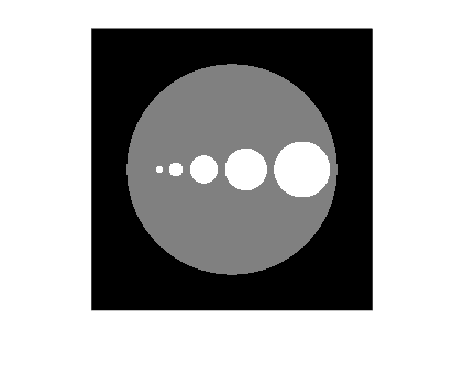

matrixTwo = generatePhantoms(N, phantomTwo, false);

# K-Space

Phantom 1 Forward FFT 

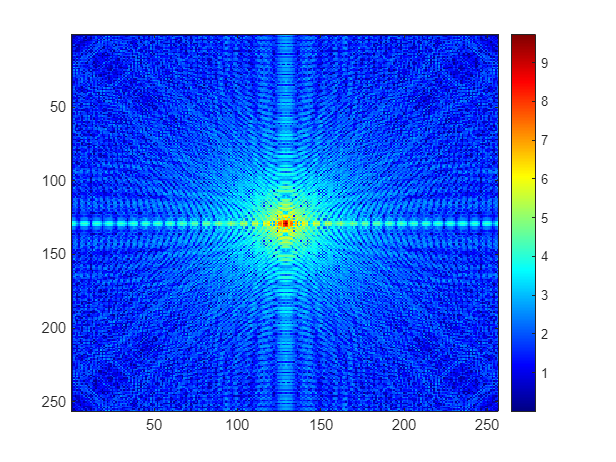

% Generate and show the k-space of a phantom
function kspace = fftTransform(matrix, direction, phantomNumber)
    if direction == "forward"
        color = "jet";
        fprintf("Phantom %d Forward FFT ", phantomNumber);
        kspace = fft2(matrix);
        imageArray = log(1 + abs(fftshift(kspace)));
    else
        color = "gray";
        fprintf("Phantom %d Inverse FFT", phantomNumber);
        kspace = ifft2(matrix);
        imageArray = abs(kspace);
    end

    figure;
    imagesc(imageArray);
    colormap(color);
    colorbar;
end

% Get FFT images for both phantoms
fftOne = fftTransform(matrixOne, "forward", 1);

Phantom 2 Forward FFT 

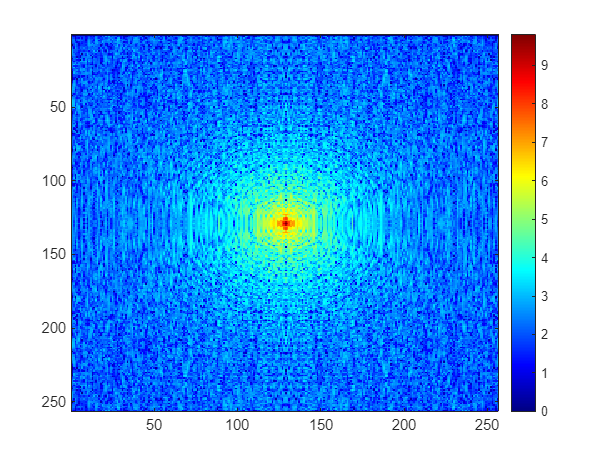

fftTwo = fftTransform(matrixTwo, "forward", 2);

Phantom 1 Inverse FFT

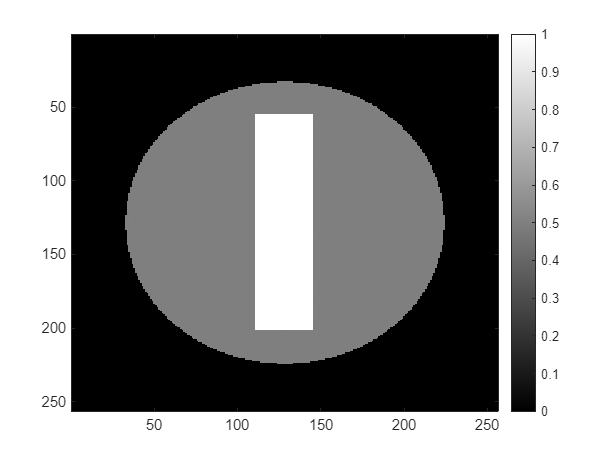


% Run FFT inverse to show that it all works correctly
fftOneReverse = fftTransform(fftOne, "inverse", 1);

Phantom 2 Inverse FFT

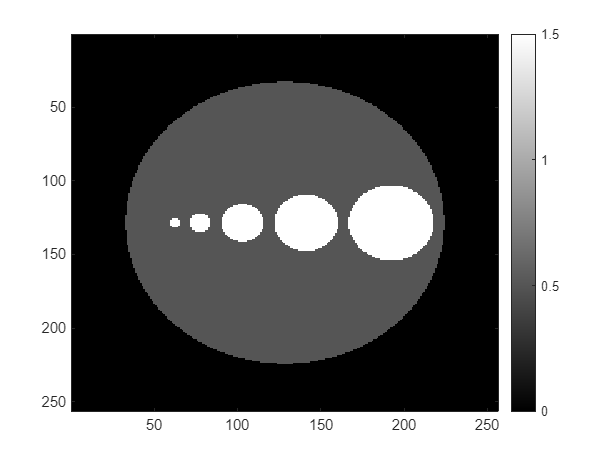

fftTwoReverse = fftTransform(fftTwo, "inverse", 2);

# Cartesian Acquisition Trajectory

% Cartesian Acquisition Trajectory which returns final image matrix given user parameters
function reconstruction = cartesianSample(matrix, width, pointDensity, lineDensity, swap)
    [rows,cols] = size(matrix);
    reconstruction = [];
    if swap == true
        rowSpacing   = ceil(cols / pointDensity);
        pointSpacing = ceil(rows / lineDensity);
    else
        rowSpacing   = ceil(rows / lineDensity);
        pointSpacing = ceil(cols / pointDensity);
    end

    for i=1:rowSpacing:width
        row = [];
        for j=1:pointSpacing:width

            if swap == true
                point = matrix(j,i);
            else
                point = matrix(i,j);
            end
            row = [row, point];
        end
        reconstruction = [reconstruction; row];
    end
end

% Radial Acquisition Trajectory which returns final image matrix given user parameters
function reconstruction = radialSample(matrix, pointDensity, lineDensity)
    [rows,cols] = size(matrix);
    reconstruction = zeros(rows)
end

Phantom 1 Inverse FFT

% This must be modified to work with the GUI to set applicable parameters
% The following are variables to be set via the GUI:
matrixWidth                    = 256; % int GUI MODIFIED VARIABLE
linePointDensity               = 256; % int GUI MODIFIED VARIABLE
horizontalLineDensity          = 256; % int GUI MODIFIED VARIABLE
swapHorizontalAndVerticalLines = false; % boolean GUI MODIFIED VARIABLE

% Reconstruct both phantoms according to user parameters
reconstructionOne = cartesianSample(fftOne, matrixWidth, linePointDensity, horizontalLineDensity, swapHorizontalAndVerticalLines);
postFFTOne = fftTransform(reconstructionOne, "inverse", 1);

Phantom 2 Inverse FFT


reconstructionTwo = cartesianSample(fftTwo, matrixWidth, linePointDensity, horizontalLineDensity, swapHorizontalAndVerticalLines);
postFFTTwo = fftTransform(reconstructionTwo, "inverse", 2);

# Radial Acquisition Trajectory

% This must be modified to work with the GUI to set applicable parameters
% The following are variables to be set via the GUI:
linePointDensity  = 50; % int GUI MODIFIED VARIABLE
radialLineDensity = 100; % int GUI MODIFIED VARIABLE

% Reconstruct both phantoms according to user parameters

# Graphical User Interface Setup

% Options to select an acquisition trajectory (Cartesian or Radial)
% Sub options to tune data acquisition parameters

# Image Reconstruction

% Set acquisition trajectories according to parameters and display